# Boundary tracing

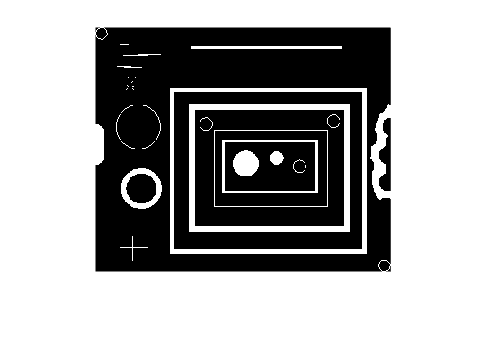

BW = imread('blobs.png');
imshow(BW)

Pick an object in the image and trace the boundary. To select an object, specify a pixel on its boundary. This example uses the coordinates of a pixel on the boundary of the thick white circle, obtained through visual inspection using `impixelinfo`. By default, `bwtraceboundary` identifies all pixels on the boundary.

r1 = 163;
c1 = 37;
contour = bwtraceboundary(BW,[r1 c1],'W');

It is useful to be able to construct and display a binary image formed from a set of boundaries. function bound2im works here

g1 = bound2im(contour,size(BW,1),size(BW,2));

Unrecognized function or variable 'bound2im'.

imshow(g1)

If we change the initial b and c (here as r1 and c1), what would happed?

r2 = 68;
c2 = 95;
contour = bwtraceboundary(BW,[r2 c2],'W');

g2 = bound2im(contour,size(BW,1),size(BW,2));
imshow(g2)


# Extracting regions and their boundaries

The boundary of a region is defined as a set of pixels in the region that have one or more neighbors that are not in the region. Initially we are interested in binary images, so foreground pixels are represtned by 1s and background pixels by 0s. Later in this chpater we will allow pixels to have gray and multispectral values. 

Using the preceding concepts, we define a hole as a set of background pixels surrounded by a connected boder of foreground pixels. A region with no holes only has an exterior boundary. Region boundaries that enclose any holes are interior boundaries. 

Using bwperim in the toolbox to obtain an image that contains only the exterior and interior boundaries of all regions in the image

f = imread('nested-binary-regions.tif');
conn = 8;
BW = bwperim(f,conn);
imshowpair(f,BW,'montage')

Note: the function bwperim return a logical image in which boundary pixels are 1 valued. The second agument conn represents the desired connectivities - 4, 8, etc. 

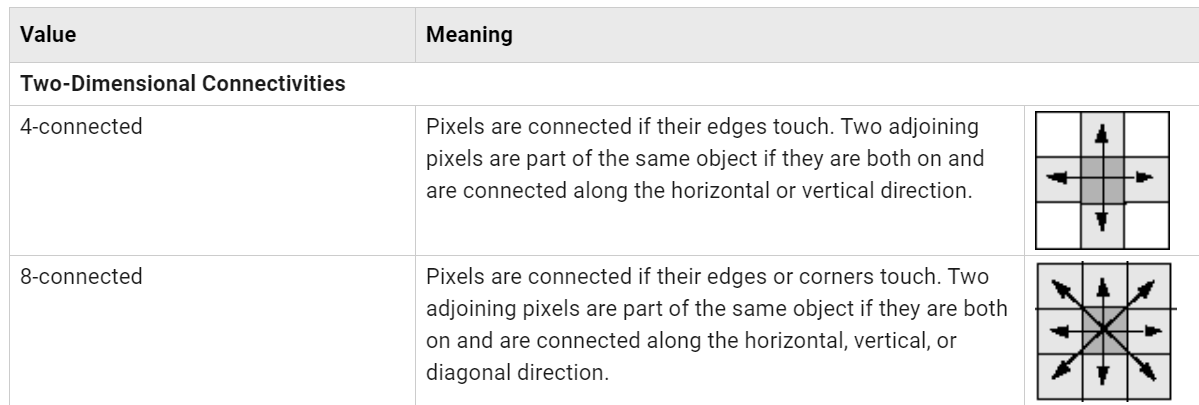

While bwperim outputs a binary image containing boundaries, the function bwboundaries extracts the actual coordinates of those boundaries as below

options = 'holes';
[B, L, NR, A]=bwboundaries(f,conn, options);

where options is a string that specifies 'holes' for extrating all exterior and any interior boundaries. Or 'noholes' for extrating only exterior boundaries, even if holes are present. 

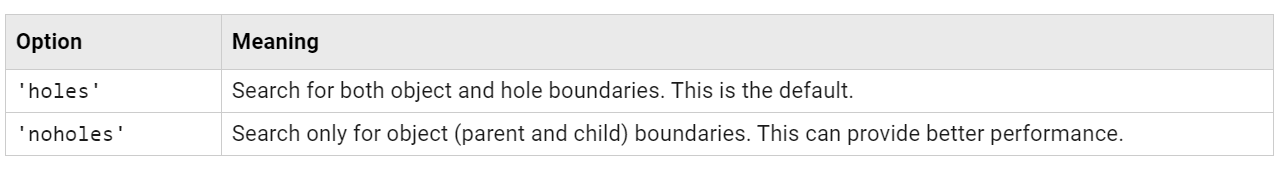

Output B is a P $\times$1 cell array where P is the number of external and internal boundaries found in f. The external boundaries are listed first in B, followed by internal boundaries. Each cell in B contains a matrix whose rows are the row and column coordinates of boundary pixels. 

Output L is a label matrix of the same size as f such that every pixel in the kth region or hole in f is identified by the elements in L that have value k (background pixels are labeled 0). Ourput NR is the number of regions found and A is a logical sparse that contains the parent/child relationships between external and internal boundaries. 

size(B)
disp(B)

Function bwtraceboundary traces the outline of a region. 

rgb = imread('yellowlily.jpg');
c = im2bw(rgb);
imshowpair(rgb,c,'montage')

Using bwtraceboundary with bound2im to display the internal and external boundaries:

BW = bwperim(c,conn);
imshowpair(c,BW,'montage')

# Extracting all boundaries

We illustrate the capabilities of function bwboundaries using the image as below.

f = imread('nested-binary-regions.tif');
figure, imshow(f)
[B,L,NR,A] = bwboundaries(f);


The function found a total of six internal and external boundaries:

disp(length(B)) 

There are four external boundaries:

disp(length(NR))

Two internal boudaries:

disp(length(B)-NR)
figure, imshow(label2rgb(L,@jet,[0,0,0]))

Let's plot the boundaries:

colors =['r','g','c','m'];
figure, imshow(f); hold on
for k =1:length(B)
    boundary = B{k};
    idx = mod(k,length(colors))+1;
    plot(boundary(:,2),boundary(:,1),colors(idx),'LineWidth',1)
end

# Using freeman chian codes

The objective of this example is to obtain the chain code and first difference of the object's outer boundary. It is evident by looking at Fig.13.4 (a) (In our textbook) that the noise fragments attached to the object would result in a very irregularboundary that is not truly representative of the general shape of the object. The obvious thing to do is to smooth the image first. 

f = imread('noisy-stroke.tif');
figure, imshow(f) %Fig.13.4 (a)
w = fspecial('average',9);
g = imfilter(f,w,'replicate');
figure, imshow(g)  % Fig.13.4(b)

and Figure 13.4© is the result of converting the filtered image to binary:

gbin=imbinarize(g);
figure, imshow(gbin)  

Next, we find the longest outer boundary as below:

B = bwboundaries(gbin,'noholes'); 
d = cellfun('length',B);
[maxindex,k] = max(d);
b = B{k};
gb = bound2im(b,size(gbin,1),size(gbin,2)); % Generating boundary image
figure,imshow(gb)

Let's see the shape of the boundary outer gb

size(b)

The obtianed chain code of gb directly would result in a long sequence with small variations that in this case would not berepresnetative of the general shape of the boundary. Therefore, we subsample the boundary using function bsubsamp (please call help subsamp for details)

scale = 0.025;
bss = bsubsamp(b,scale, 4, size(gbin,1),size(gbin,2)); 

Now, this reduced the number of points in the boundary from 1357 to 41:

(length(b))
(length(bss))

In order to display the 41 points of boundary bss in a size comparable, we rescale the boundary


bssr=bss/scale;
g2 = bound2im(bssr,size(gbin,1),size(gbin,2));
se = ones(3);
g2c = imdilate(g2,se);
g2c = imcolorcode(g2c,[1 1 0]);
imshowpair(gb,g2c,'montage')

Finally, we use function connectpoly to join the points for disply and comparison

cn = connectpoly(bssr(:,1),bssr(:,2));
g3 = bound2im(cn,size(gbin,1),size(gbin,2));
figure, imshow(g3)

Obtain the freeman chian code as

c = freemancc(bss)

If we change the starting point, the chain code will be adjusted as below:

new_bss = [bss(10:end,:);bss(1:9,:)];
c_new = freemancc(new_bss)

# MPP algorithms

we will use the image as below to illustrate how the MPP algorithm works. 

f = imread('mapleleaf.tif');
figure, imshow(f)
B = bwboundaries(f,4,'noholes');
b = B{1};
% Number of points on the boundary
npb = size(b,1)

Display the boundary as in mage

imb = bound2im(b,size(f,1),size(f,2));
figure, imshow(imcolorcode(imb,[0 1 1]))

Applying MPP

size_number = 2;
[X,Y] = im2minperpoly(f,size_number);
    % Number of MPP vertices.
    nv2 =numel (X)
    b2 =connectpoly(X,Y);
    % b2 is the new coordinates after applying MMP
    npb2 = size(b2,1);
    imb2 = bound2im(b2,size(f,1),size(f,2));
    figure, imshow(imcolorcode(imb2, [ 0 1 1]))

This figures shows that using a cell of size 2 $\times$ 2 results in an MPP that is a good approximation of the original boundary. We could change the cell of size to 4, 6, 8, 16, 32. Once we change the cell size, the results lost some major relevant features of the objects, but data compression achieves.

There are two significances. First, we need to store only the vertices case, the data compression is significant. Second, it is that polygonal approximations lend themselves more readily than raw boundaries for basic shape features which are independent of position, scale, and rotation. 